# example for importance sampling of SRP (Ashikhmin–Shirley model)

モンテカルロ積分に使う乱数の数は `nMCint`

`それを nMC `回行って平均と分散を計算し，plotする．（ややこしい）

clc
clear
cls

format long

## Monte-Carlo condition & pre-allocation

nMC = 2;

srpTrue = zeros(nMC, 3);
srpImp = zeros(nMC, 3);


## object

sat = readSC('flatPlate.obj', 1)

Reading Object file : flatPlate.obj
  % Blender v2.91.2 OBJ File: 'flatPlate.blend'
  %www.blender.org
Reading Material file : flatPlate.mtl
  % Blender MTL File: 'flatPlate.blend'
  % Material Count: 1
Finished Reading Material file
Finished Reading Object file


ans =      8     3


ans =     12     3


sat = フィールドをもつ struct :
    vertices: [8×3 double]
       faces: [12×3 double]
        area: [12×1 double]
         pos: [12×3 double]
      normal: [12×3 double]
          uu: [12×3 double]
          uv: [12×3 double]
         qlb: [12×4 double]
          Ca: [12×1 double]
          Cd: [12×1 double]
          Cs: [12×1 double]


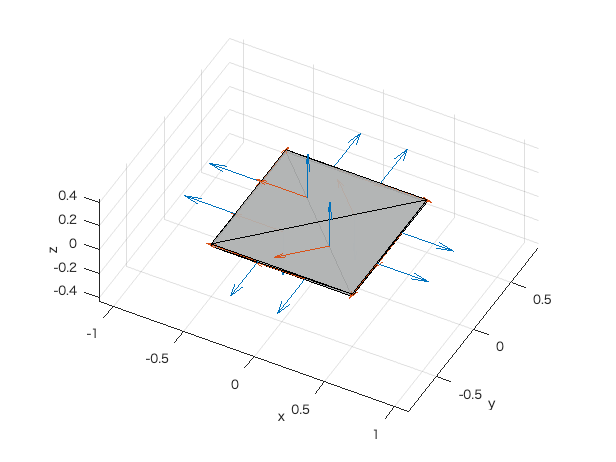

showSC(sat, 'Normal', 'on');

sat.rho = 0.5;
sat.F0 = 0.5;
sat.nu = 800;
sat.nv = 150;

const = orbitConst;
d = au2km(1, const) * 10^3; % m
dAU = km2AU(d ./ 10^3, const); % AU
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;

## Ashikhmin–Shirley model

thetaI = deg2rad(20);
phiI = deg2rad(48);
sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI), cos(thetaI)];
sunB = sunB ./ norm(sunB);

% Monte-Carlo integration condition
nMCintUni = [1000, 5000, 10000, 50000, 100000, 10^6];
nMCintUni = [100000 10^6];

tic
for i = 1:length(nMCintUni)
    N = nMCintUni(i);
    for j = 1:nMC

## speuclar only, uniform distribution

        [~, ~, srpCs] = srpASuni(sat, sunB, d, const, N);

        srpTrue(j,:) = srpCs;
    end
    stdTrue(i,:) = std(srpTrue);
    meanTrue(i,:) = mean(srpTrue);
end
toc

経過時間は 1.141947 秒です。


## importance sampling

% Monte-Carlo integration condition
% nMCint = 10:200:10000;
nMCintImp = [100 10^4];
nMCintImp = nMCintUni;

tic
for i = 1:length(nMCintImp)
    N = nMCintImp(i);
    for j = 1:nMC
        [~, ~, srpCs] = srpAS(sat, sunB, d, const, N);   
        srpImp(j,:) = srpCs;
    end

    stdImp(i,:) = std(srpImp);
    meanImp(i,:) = mean(srpImp);
end

toc

経過時間は 0.646958 秒です。


## show Figs

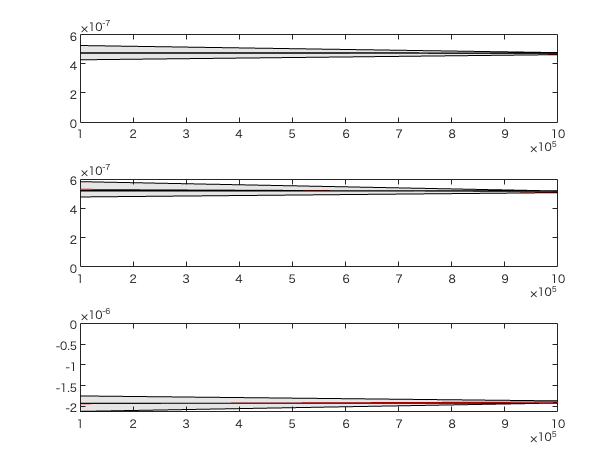

figure
tiledlayout(3,1), nexttile
plotStd(nMCintUni, meanTrue(:,1), 3*stdTrue(:,1), 'r'), hold on
plotStd(nMCintImp, meanImp(:,1), 3*stdImp(:,1), 'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,2), 3*stdTrue(:,2)); hold on
plotStd(nMCintImp, meanImp(:,2), 3*stdImp(:,2),'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,3), 3*stdTrue(:,3)); hold on
plotStd(nMCintImp, meanImp(:,3), 3*stdImp(:,3), 'b', 'b');


[meanTrue(end,:)
    meanImp(end,:)]

ans = 1.0e-05 *

   0.046968071011663   0.051409020462845  -0.189149439174868
   0.047418663312269   0.052133024870338  -0.192019505333811
